**Plotting the conditional probabilities**

figure;
j=1;
r_select=5;
plot(tau(1:tau_length)*10^3,pi_1(r_select,:),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
legend({'$\pi_1$'},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
%plotting the vertical line
T_settings=T_loc+T_IRS;
plot([T_settings T_settings]*10^3,[0 1],'--','LineWidth',2,'Color','black');
text(T_settings*10^3,0.2,strcat('$T_\mathrm{conf}=T_\mathrm{loc}+T_\mathrm{IRS}\approx',num2str(T_settings*10^3,'%.0f'),'\,$ms'),'Interpreter','latex','FontSize',fontsize);
annotation('arrow', [0 0.05], [0 0.05]);
axis([0 40 0 1])

grid on;
hold off %to close the canvas
xlabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

p = get(gca, 'Position');
h = axes('Parent', gcf, 'Position', [p(1)+.06 p(2)+.06 p(3)-.5 p(4)-.5]);

j=2;

j = 2

plot(h,tau(1:tau_length),pi_2(r_select,:),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
j=3;

j = 3

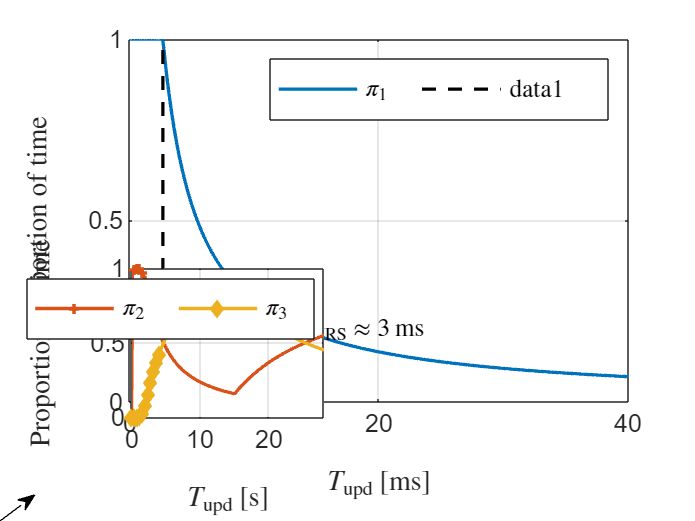

plot(h,tau(1:tau_length),pi_3(r_select,:),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;


grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);

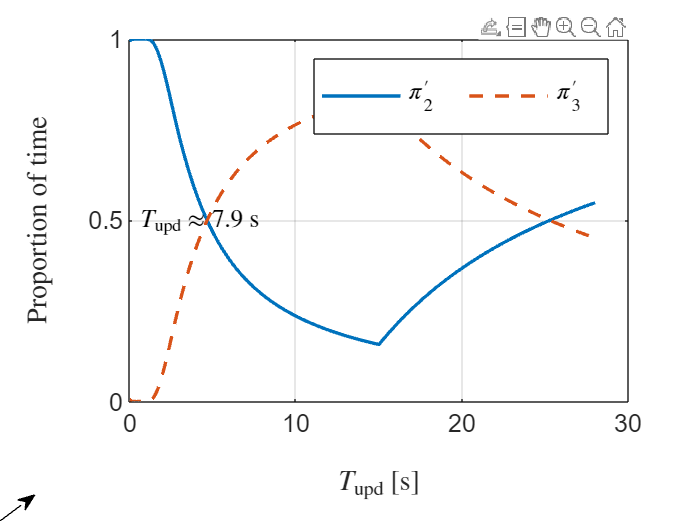



figure;
j=1;
sample_shift=ceil((T_loc+T_IRS)/delta_tau_j)+1;
plot(tau(1:tau_length),pi_norm_2(r_select,:),'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
plot(tau(1:tau_length),pi_norm_3(r_select,:),'--','Color',color{j+1},'LineWidth',2,...
        'MarkerEdgeColor',color{j+1},'MarkerFaceColor',color{j+1},'MarkerIndices',1:round(tau_length/10):tau_length);

%Annotation
text(0.5,0.5,strcat('$T_\mathrm{upd}\approx 7.9$ s'),'Interpreter','latex','FontSize',fontsize);
annotation('arrow', [0 0.05], [0 0.05]);
% axis([0 20 0 1]);

grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi''_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);


saveas(gcf, './results/pi_2_3_v2.fig');
saveas(gcf, './results/pi_2_3_v2.svg');

Error using saveas
Invalid or missing path: ./results/pi_2_3_v2.fig

**PAoI**

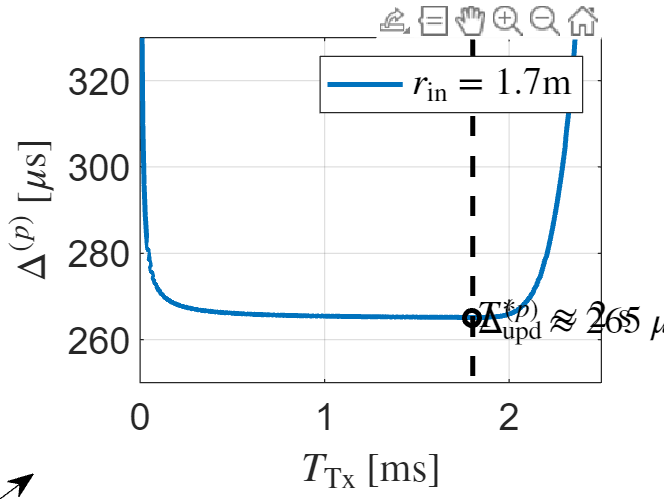

figure;
total_curves=1;
step=ceil(length(r_inner)/total_curves);
r_select=5;
[~,tau_length]=size(PAoI(1,:));
j=1;
plot(T_upd(1:tau_length),PAoI(r_select,:)*10^6,...
     marker{j},'LineWidth',2,'MarkerIndices',1:round(tau_length/10):tau_length); hold on;

%plotting the minimum

[Min,idx]=min(PAoI(r_select,:));
plot(tau(idx),Min*10^6,'o','LineWidth',2,'Color','black');


%plotting the vertical line
plot([tau(idx) tau(idx)],[0.1*Min 4*Min]*10^6,'--','LineWidth',2,'Color','black');

text(tau(idx),Min*10^6,strcat('$\Delta^{(p)}\approx',num2str(Min*10^6,'%.0f'),'\, \mu$s'),'Interpreter','latex','FontSize',fontsize);
text(tau(idx),Min*10^6,strcat('$T^*_\mathrm{upd}\approx',num2str((tau(idx)),'%.0f'),'$ s'),'Interpreter','latex','FontSize',fontsize);
annotation('arrow', [0 0.05], [0 0.05]);

xlabel('$T_\mathrm{Tx}$ [ms]','Interpreter','latex');
ylabel('$\Delta^{(p)}$ [$\mu$s]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;


legend_text=strcat('$r_\mathrm{in}=',num2str(r_inner(r_select),2),'$m');
legend({legend_text},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html

hold off %to close the canvas
axis([0 2.5 250 330]);

saveas(gcf, './results/PAoI_r_0_2.fig');

saveas(gcf, './results/PAoI_r_0_2.svg');


figure;
total_curves=length(r_inner);

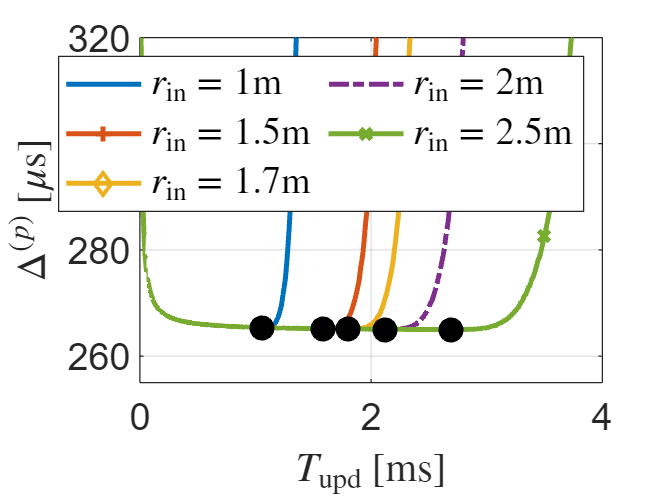

Error using saveas
Invalid or missing path: ./results/PAoI.fig

j=length(r_inner);
step=ceil(length(r_inner)/total_curves);
r=1:total_curves;%2:step:length(r_inner);
[~,tau_length]=size(PAoI(j,:));
%Plotting the average PAoI
for j=1:length(r)
     plot((0:tau_length-1)*delta_tau_j,PAoI(j,:)*10^6,marker{j},'LineWidth',2,...
         'MarkerIndices',1:round(tau_length/10):tau_length); hold on;
end

%Plotting the minimum PAoI
%time interval for channel estimation
plot((0:tau_length-1)*delta_tau_j*10^3,(T_Tx+T_d)*10^6,'--','LineWidth',2,'Color','black');

%Plotting the location of the minimum for the average PAoI
for j=1:length(r)
    [Min,idx]=min(PAoI(j,:));
    plot(tau(idx),Min*10^(6),'o','LineWidth',2,'Color','black','MarkerFaceColor','black','MarkerSize',8);
end

xlabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
ylabel('$\Delta^{(p)}$ [$\mu$s]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

%lower limit
%plot([T_overhead(1) T_overhead(1)*10^3],[0 800],'--','LineWidth',2,'Color','black');
%Annotation
%text(3,270,strcat('$T_\mathrm{loc}+T_\mathrm{IRS}+T_\mathrm{p\_ovh}\approx 2.7$ms'),'Interpreter','latex','FontSize',fontsize);
%annotation('arrow', [0 0.05], [0 0.05]);

legend_text=cell(1,length(r));
for m=1:length(r)
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end
%legend_text{m+1}='Minimum average PAoI';

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas
axis([0 4 255 320]);

saveas(gcf, './results/PAoI.fig');
saveas(gcf, './results/PAoI.svg');